## Parametros

L1 = 1;
L2 = 1;
theta_1 = 0;
theta_2 = 0;
f = [0; 0];
t = [50; 50];
a = 1.332; % 1.332 hace que el L mida ~15 (el valor mímimo que debe tener)
b = 4.71; % 4.71 hace que el trebol esté (~) sin rotar

## Puntas de los eslabones

A = [f(1)+L1*cos(theta_1); f(2)+L1*sin(theta_1)]

A =      1
     0


B = [A(1)+L2*cos(theta_1+theta_2); A(2)+L2*sin(theta_1+theta_2)]

B =      2
     0


## Trebol

theta = linspace(0, 2*pi);
trebol = [(a*(sin(4*theta+b)+6)).*cos(theta)+t(1); (a*(sin(4*theta+b)+6)).*sin(theta)+t(2)]

trebol =    56.6600   56.6884   56.7716   56.8988   57.0535   57.2143   57.3577   57.4597   57.4982   57.4551   57.3178   57.0802   56.7435   56.3154   55.8096   55.2443   54.6402   54.0188   53.4001   52.8007   52.2327   51.7026   51.2110   50.7527   50.3181   49.8943   49.4670   49.0223   48.5488   48.0387   47.4898   46.9054   46.2948   45.6724   45.0568   44.4688   43.9300   43.4600   43.0750   42.7861   42.5978   42.5077   42.5065   42.5789   42.7044   42.8599   43.0212   43.1657   43.2740   43.3322
   50.0000   50.4251   50.8642   51.3296   51.8301   52.3694   52.9456   53.5508   54.1719   54.7911   55.3879   55.9410   56.4299   56.8374   57.1510   57.3646   57.4786   57.5008   57.4451   57.3308   57.1805   57.0184   56.8677   56.7488   56.6771   56.6616   56.7044   56.7998   56.9357   57.0940   57.2528   57.3880   57.4761   57.4957   57.4299   57.2678   57.0052   56.6446   56.1956   55.6731   55.0961   54.4857   53.8632   53.2478   52.6554   52.0965   51.5762   51.0936   50.6423

esq_1 = [max(trebol(1,:)); max(trebol(2,:))]

esq_1 =    57.5032
   57.5008


esq_2 = [min(trebol(1,:)); min(trebol(2,:))]

esq_2 =    42.5065
   42.4996


## Deducción

Tenemos que hacer que B == trebol.

### En x

A(1)+L2*cos(theta_1+theta_2) == (a*(sin(4*theta+b)+6)).*cos(theta)+t(1)

f(1) + L1*cos(theta_1) + L2*cos(theta_1+theta_2) == (a*(sin(4*theta+b)+6)).*cos(theta) + t(1)

L1*cos(theta_1) + L2*cos(theta_1+theta_2) == (a*(sin(4*theta+b)+6)).*cos(theta) + t(1) - f(1)

L1*cos(theta_1) + L2*cos(theta_1+theta_2) == N

### En y

A(2)+L2*sin(theta_1+theta_2) == (a*(sin(4*theta+b)+6)).*sin(theta)+t(2)

f(2) + L1*sin(theta_1) + L2*sin(theta_1+theta_2) == (a*(sin(4*theta+b)+6)).*sin(theta) + t(2)

Buscamos L1 y L2 tal que las ecuaciones se cumplan para cualquier valor de theta_1 y theta_2.

## Gráfica

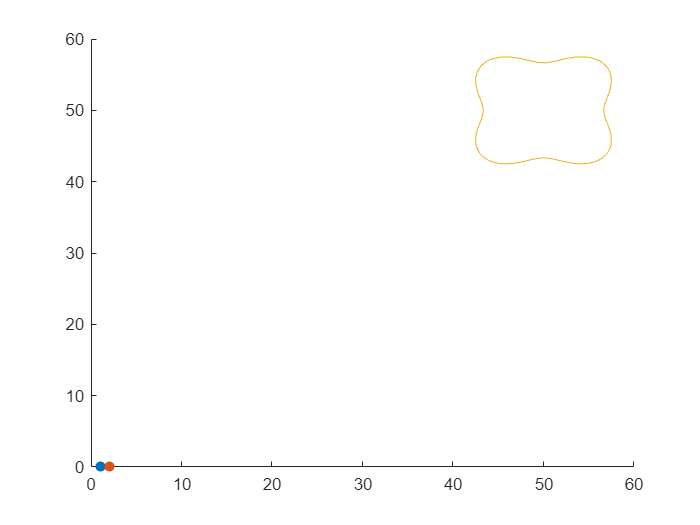

scatter(A(1), A(2), 'filled');
hold on;
scatter(B(1), B(2), 'filled');
plot(trebol(1,:),trebol(2,:));
hold off;